energy_distribution = readmatrix("Energy_Distribution.xlsx");

energy_distribution = fliplr(energy_distribution);
energy_distribution = energy_distribution(:, :);

## Export to png

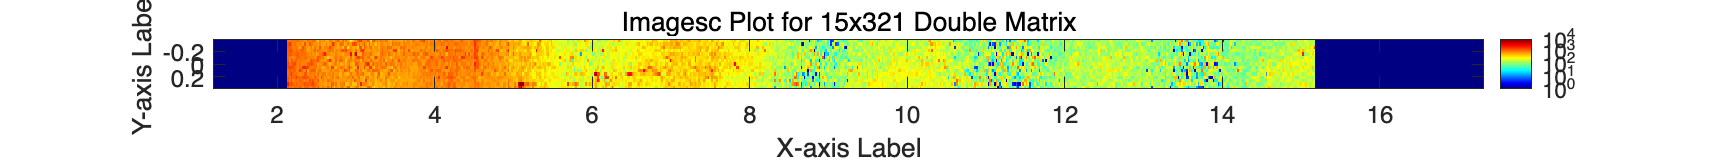

im = imagesc(1.196:0.052:17.356, -0.364:0.052:0.364, log10(energy_distribution));
% 색상 막대 추가
c = colorbar;
% 컬러바의 틱을 로그 스케일에 맞게 설정
c.Ticks = log10([1.2 10 100 1000 7000]); % 원하는 로그 스케일 값으로 설정
c.TickLabels = arrayfun(@(x) sprintf('10^{%.0f}', x), c.Ticks, 'UniformOutput', false); % 실제 값으로 라벨 표시

% 축 레이블 추가
xlabel('X-axis Label');
ylabel('Y-axis Label');

% 제목 추가 (필요에 따라 생략 가능)
title('Imagesc Plot for 15x321 Double Matrix');

% 축 폰트 크기 설정
set(gca, 'FontSize', 12);

% 그래프 크기 조정 (논문 형식에 맞게)
set(gcf, 'Position', [100, 100, 1605, 150]); % 가로x세로 픽셀 단위로 설정

% 색상 지도 설정 (논문에 적합한 색상 팔레트 선택)
colormap(jet);

% 그래프 저장 (고해상도 이미지로 저장, 해상도는 필요에 맞게 설정)
filename = sprintf('log_imagesc_plot.png');
print(filename, '-dpng', '-r300'); % PNG 파일로 300 dpi 해상도로 저장